% files = ["data20", "data-20", "data40", "data-40", "data60", "data-60", "data80", "data-80", "data100", "data-100"];
files = ["data-100", "data-80", "data-60", "data-40", "data-20", "data20", "data40", "data60", "data80", "data100"];
voltages = [-100,-80,-60,-40,-20,20,40,60,80,100]; %
k_all = [];
Tm_all = [];
for i=1:10
    data = readmatrix(files(i));
    time=data(:,1);
    U = voltages(1);
    
    angle=data(:,2)*pi/180;
    omega=data(:,3)*pi/180;
    
    
    % approximation - let's take
    lol0 = [0.1 ; 0.06];
    % given voltage in percents
    U_pr = 100;
    % 0(t) = ...
    func = @(lol, time) U_pr*lol(1)*(time - lol(2)*(1 - exp(-time/lol(2))));
    % Nonlinear least-squares solver %
    solver = lsqcurvefit(func,lol0,time,angle);
    k = solver(1);
    Tm = solver(2);
    k_all(i) = k;
    Tm_all(i) = Tm;
    
    
    
end


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr

w_nls = U_pr*k_all

w_nls =   -20.7083  -16.6673  -12.4312   -7.9563   -3.4698    3.4845    7.9981   12.5718   17.0439   22.0461


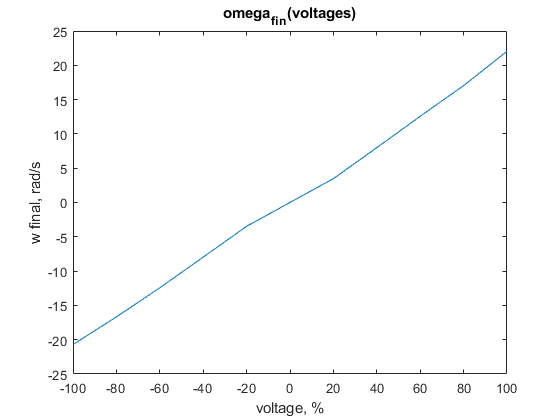

figure(1)
plot(voltages,w_nls);
title("omega_f_i_n(voltages)")
xlabel("voltage, %")
ylabel("w final, rad/s")

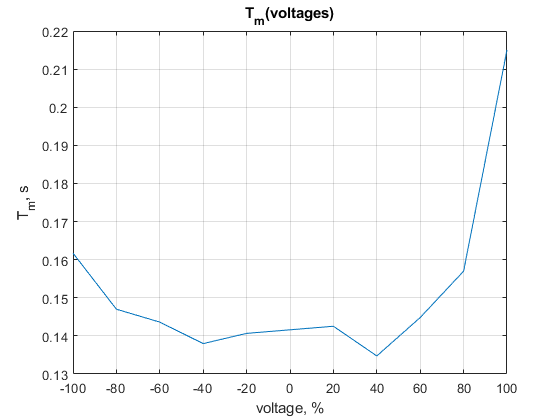




figure(2)
plot(voltages,Tm_all);
title("T_m(voltages)")
xlabel("voltage, %")
ylabel("T_m, s")
grid on

k_all

k_all =    -0.2071   -0.1667   -0.1243   -0.0796   -0.0347    0.0348    0.0800    0.1257    0.1704    0.2205


Tm_all

Tm_all =     0.1617    0.1470    0.1436    0.1380    0.1407    0.1425    0.1347    0.1448    0.1570    0.2151
